002_1，使用训练好的网络执行语义分割并且保存预测图像

Running semantic segmentation network
-------------------------------------
* Processed 21 images.



Evaluating semantic segmentation results
----------------------------------------
* Selected metrics: global accuracy, class accuracy, IoU, weighted IoU, BF score.
* Processed 21 images.
* Finalizing... Done.
* Data set metrics:

    GlobalAccuracy    MeanAccuracy    MeanIoU    WeightedIoU    MeanBFScore
    ______________    ____________    _______    ___________    ___________

       0.87838          0.82073       0.57304      0.83621        0.90568  



ans = 2×2 table
                     Sand       Small_Rock
                  __________    __________

    Sand          4.5834e+06    5.8779e+05
    Small_Rock         81757    2.5211e+05


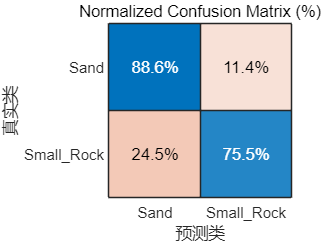

do_prediction=1;
if do_prediction
    %加载数据集
    clc
    clear
    load imageLabelData002\gTruth_sand_smallRock_002_train.mat
    [imdstrain,pxdstrain]=pixelLabelTrainingData(gTruth);
    load imageLabelData002\gTruth_sand_smallrock_002_test.mat
    [imdstest,pxdstest]=pixelLabelTrainingData(gTruth);
    %加载训练好的网络
    load Result002\003_DeepLabv3+_resnet50_2023-11-27-19-09.mat
    %执行预测
    pxdsresult=semanticseg(imdstest,net,"MiniBatchSize",10);
    metrics=evaluateSemanticSegmentation(pxdsresult,pxdstest);
    metrics.ConfusionMatrix
    classname=pxdstrain.ClassNames;
    pixelLabelID = gTruth.LabelDefinitions.PixelLabelID ;
    figure
    cm = confusionchart(metrics.ConfusionMatrix.Variables, ...
      classname, Normalization='row-normalized');
    cm.Title = 'Normalized Confusion Matrix (%)';
    %name=strcat('003_confusionchart_',string(modelDateTime),'.png')
    %saveas(gcf,strcat('Result002\',name))
end

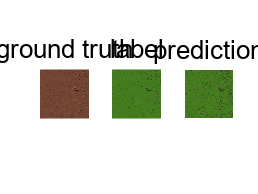

%保存预测结果
do_show_002_1=1;
if do_show_002_1
    im_prediction_location=dir("*.png");
    im_prediction_location=natsortfiles(im_prediction_location);
    %cmap=gTruth.LabelDefinitions.LabelColor;
    cmap=[0 0.8 0;0 0.45 0.07];
    imwritelocation='Result002\image\';
    imFrom='testSet_';
    for i=1:numel(im_prediction_location)
        I1=imread(imdstest.Files{i});
        subplot(1,3,1);
        imshow(I1);
        title('ground truth','FontSize',20);
        
        C1=imread(pxdstest.Files{i});
        subplot(1,3,2);
        I2 = labeloverlay(I1,C1,"Colormap",cmap, ...
                    "Transparency",0.6);
        imshow(I2);
        title('label','FontSize',20);
    
        C2=imread(im_prediction_location(i).name);
        subplot(1,3,3);
        I3 = labeloverlay(I1,C2,"Colormap",cmap, ...
                    "Transparency",0.6);
        imshow(I3);
        title('prediction','FontSize',20);
        saveas(gcf,strcat(imwritelocation,imFrom,string(i),'_','show','.png'))
        
        I1_name=strcat(imwritelocation,imFrom,string(i),'_','1_G','.png');
        imwrite(I1,I1_name)
        I2_name=strcat(imwritelocation,imFrom,string(i),'_','2_L','.png');
        imwrite(I2,I2_name)
        I3_name=strcat(imwritelocation,imFrom,string(i),'_','3_P','.png');
        imwrite(I3,I3_name)
    end
    delete('*.png')
end